# **Review of Numerical Programming - for Final Exam**

**by Y.-K. Kim**

Created: 2024.11

# **Linear Equations**

## Problem

Find the tension force between B and C (F_BC) in Truss

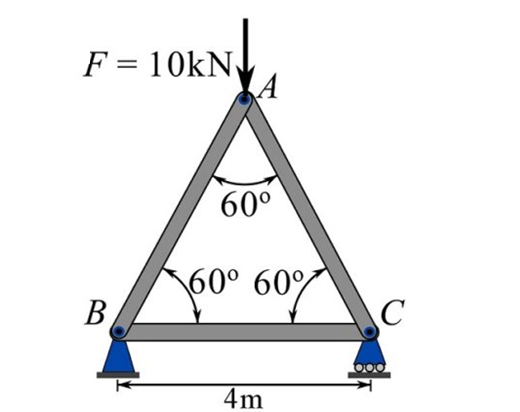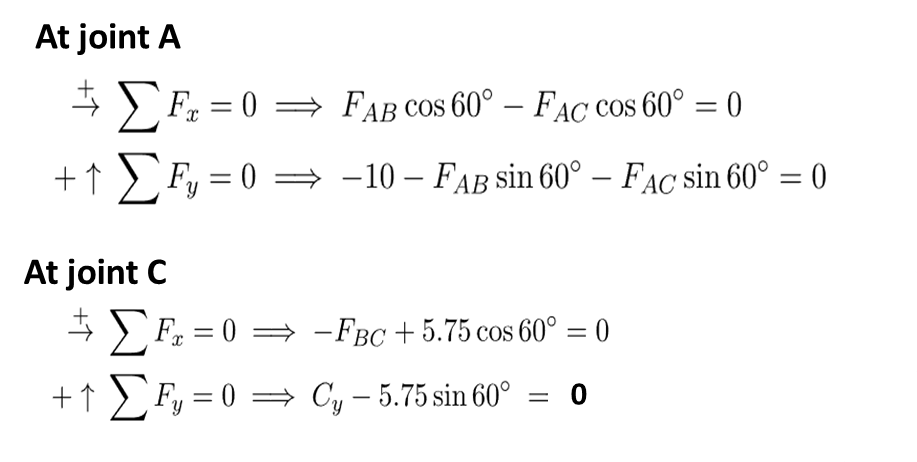

% A, b
A=[0.5 -0.5 0 0; 0.87 0.87 0 0;0 0 1 0;0 0 0 1];
b=[0; -10; -5.75*cos(60/180*pi); 5.75*sin(60/180*pi)];

% Rank 
rank(A)

ans = 4

% Conditional Number
cond(A)

ans = 1.7400


% Solve for Ax=b
% x=inv(A)*b
x=A\b   

x =    -5.7471
   -5.7471
   -2.8750
    4.9796



% Solution
Fbc=x(3)

Fbc = -2.8750

# **Eigenvalue/vector **

**A mass-damping-spring system dynamic is**

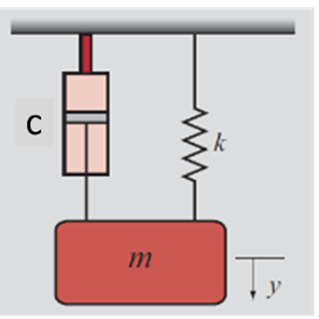

**Find the response y(t) and dy****/dt(t) by solving for eigenvalue and vectors **

**Also, compare the response with the solution using ODE-IVP**

Use  m=10kg ; k=800 N/m; c=200 N/(m/s)

Initial condition  y(0)=0,  dy/dt(0)=0,  h=0.01

clear; close all;

% Model
k=800; c=200; m=10;
A = [0 1; -k/m, -c/m];

% Eigvalue/vector
disp('Eigvalue and vector of A (MATLAB):');

Eigvalue and vector of A (MATLAB):


[V,S]=eig(A)

V =     0.1780   -0.0689
   -0.9840    0.9976


S =    -5.5279         0
         0  -14.4721


eigval=diag(S);


% Initial Condition
yINI = 0;
vINI = 0.1;
b=[yINI;vINI];

% Constant coeffient for initial values
c=(V)\b

c =     0.0628
    0.1622


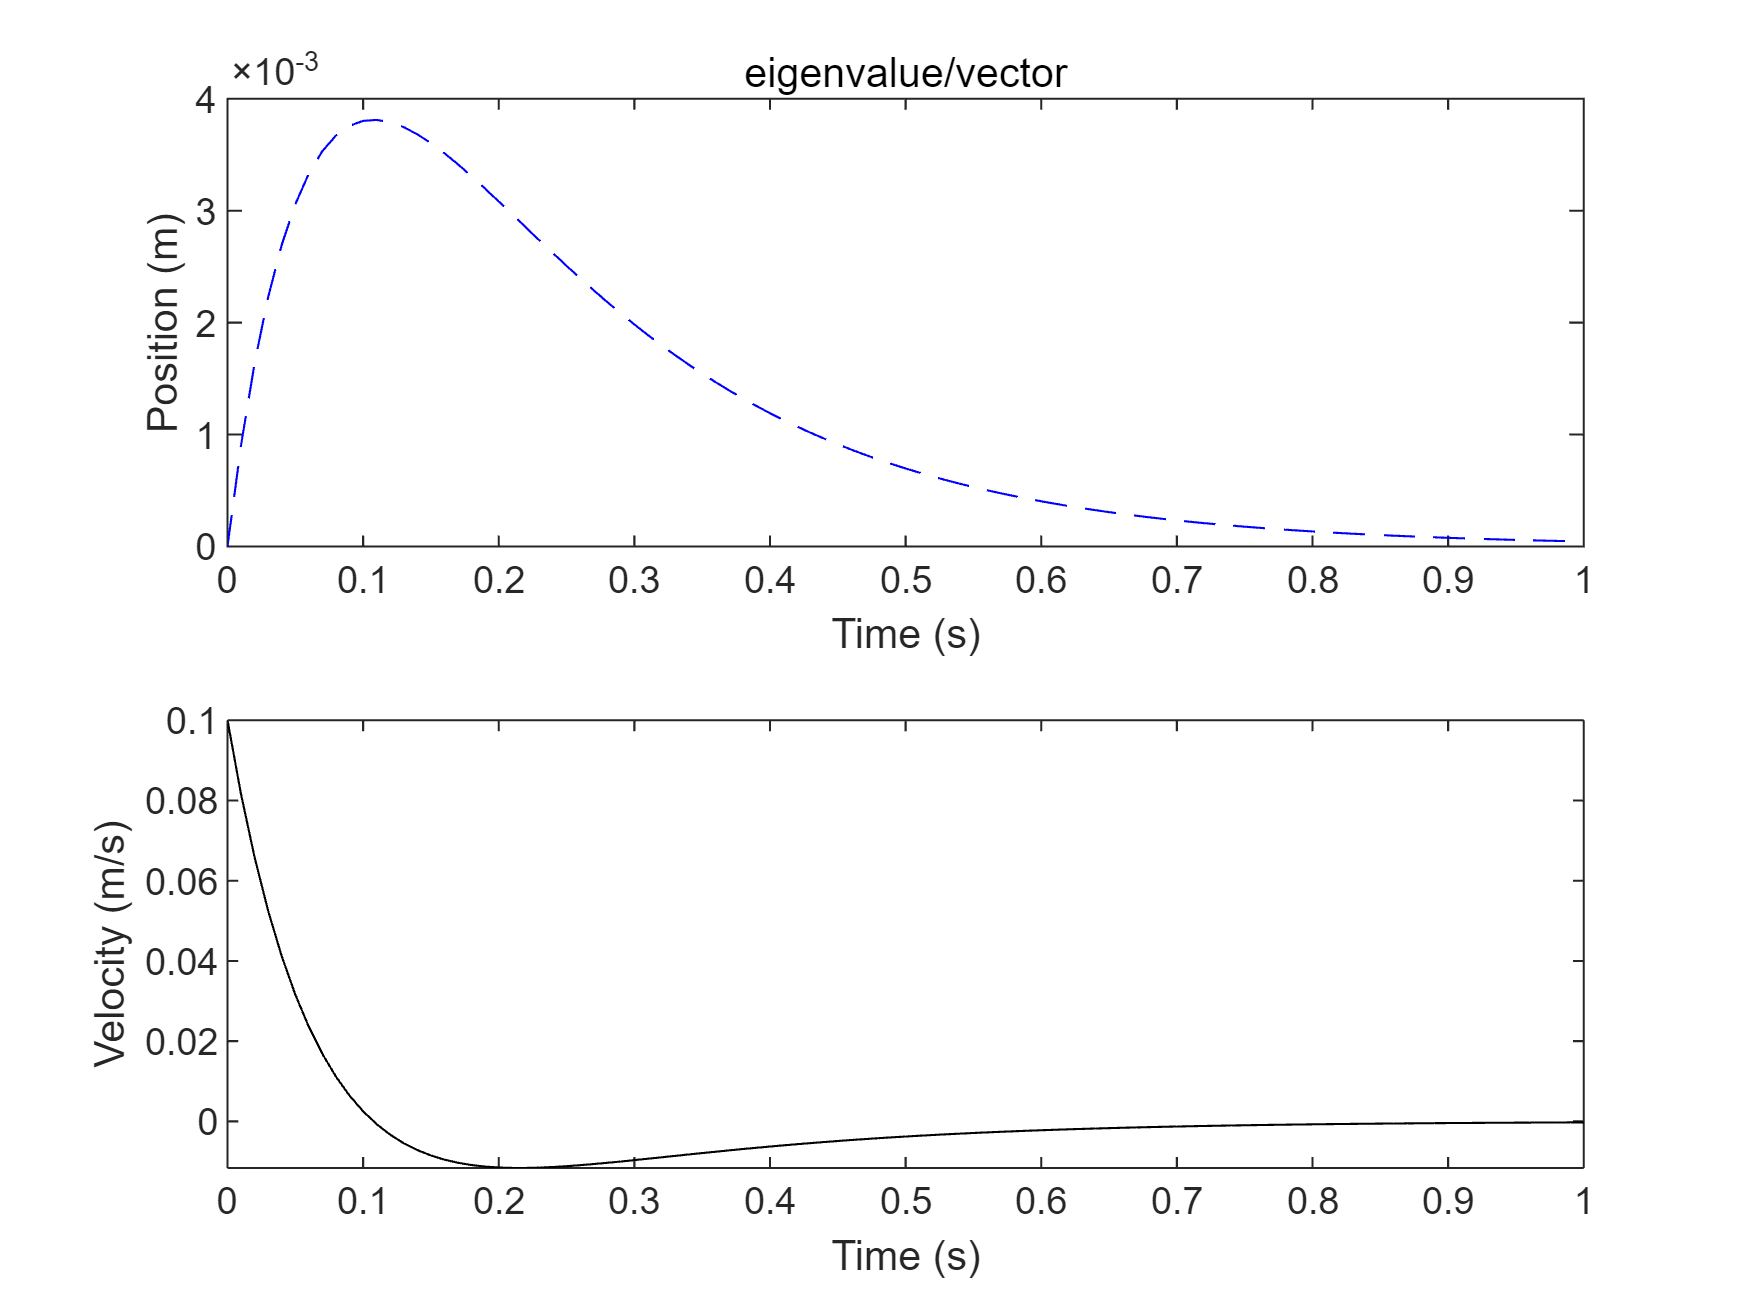


% Response of the system
t=0:0.01:1;
vecY=c(1)*V(:,1)*exp(eigval(1).*t)+c(2)*V(:,2)*exp(eigval(2).*t);
disY=vecY(1,:);
velY=vecY(2,:);


figure
subplot(2,1,1)
    plot(t,disY,'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('eigenvalue/vector')
subplot(2,1,2)
    plot(t,velY,'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

# **1st order ODE-IVP**

## Problem

Solve for the response of an RC circuit with a DC  input 

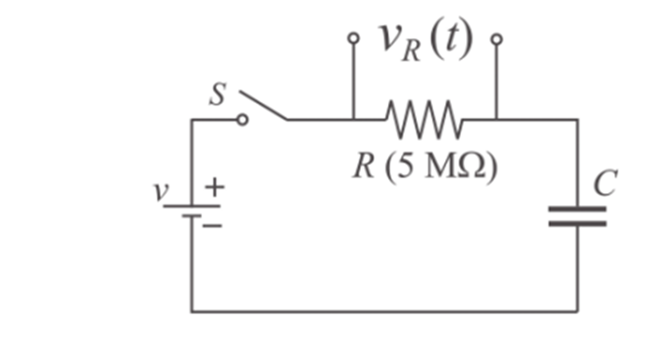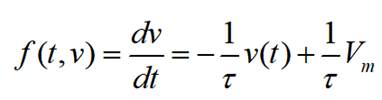

Use h=1,  for  t=0 to 15  sec, tau=4.9919;  Vm=11.91;

**Parameter Definitions**

clear
close all

% Initial Condition
a=0; b=15; h=1; 
t=a:h:b;
y0 = 11.91;

ytrue(1) = y0;
N = (b-a)/h;

### ode45()

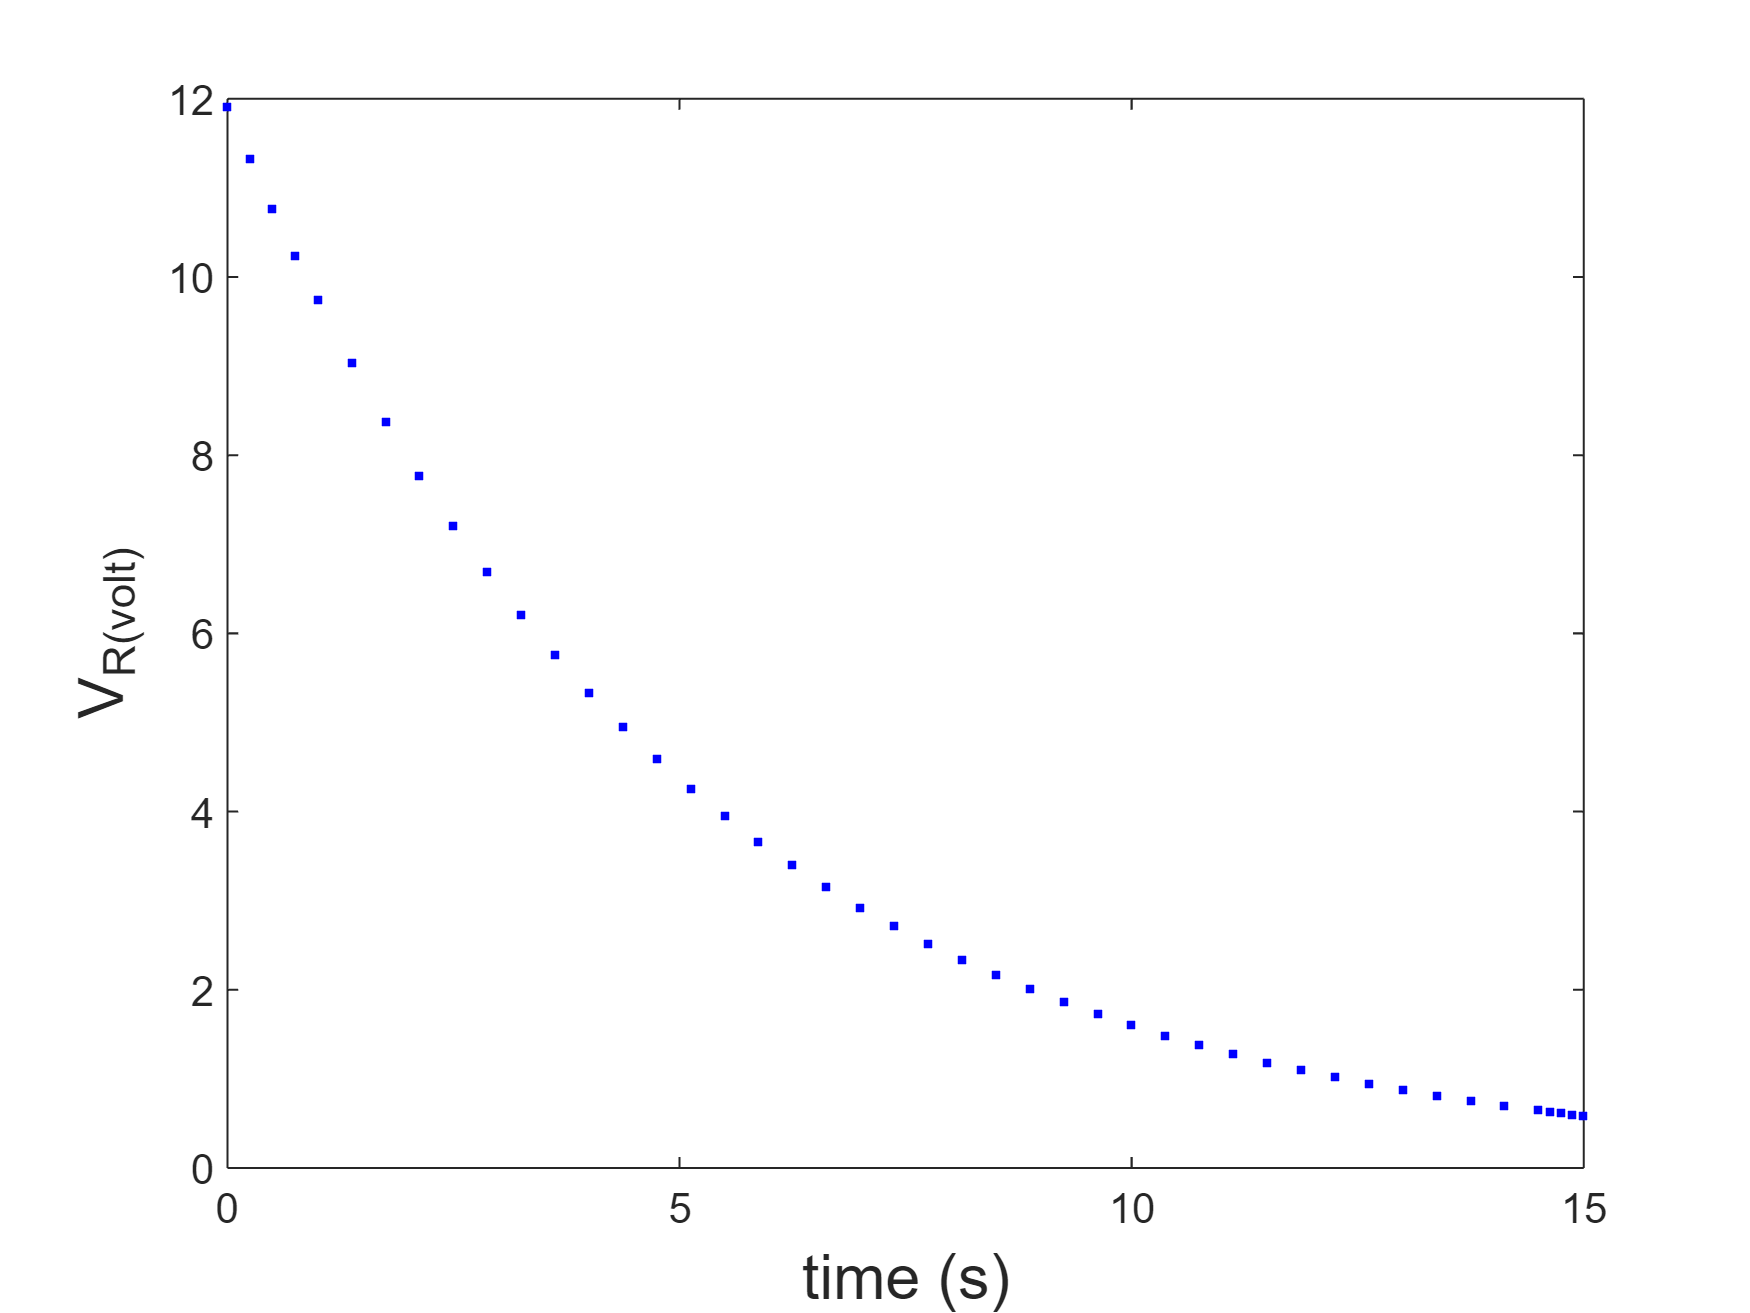

%% MATLAB's function ODE45
[tmat,vmat] = ode45(@myRC, [a b], y0);  % Fourth/Fifth RK

figure()
plot(tmat,vmat,'.b')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

The RC function is defined in @myRC(t,v)

% function dvdx = myRC(t,v)
%    tau=4.9919; T=1/tau;  Vm=0;
%    dvdx =-T*v + 1*T*Vm;
% end


# **ODE-IVP:  2nd order **

## Problem 1

Find the displacement response y(t) and dydt(t) with no external force,

  where,  F(t)=0

Use  m=10kg ; k=800 N/m; c=200 N/(m/s), f=10Hz , h=0.01

Also, compare with the response from eigenvalue/vector method.  t=0sec, t=0.1, t=1sec

**Parameter Definition**

close all

% Initial Condition
a=0;
b=1;
h=0.01;
tspan = [a:h:b];
N = (b-a)/h;

yINI = 0;
vINI = 0.1;
Yini = [yINI vINI];

### ode45()

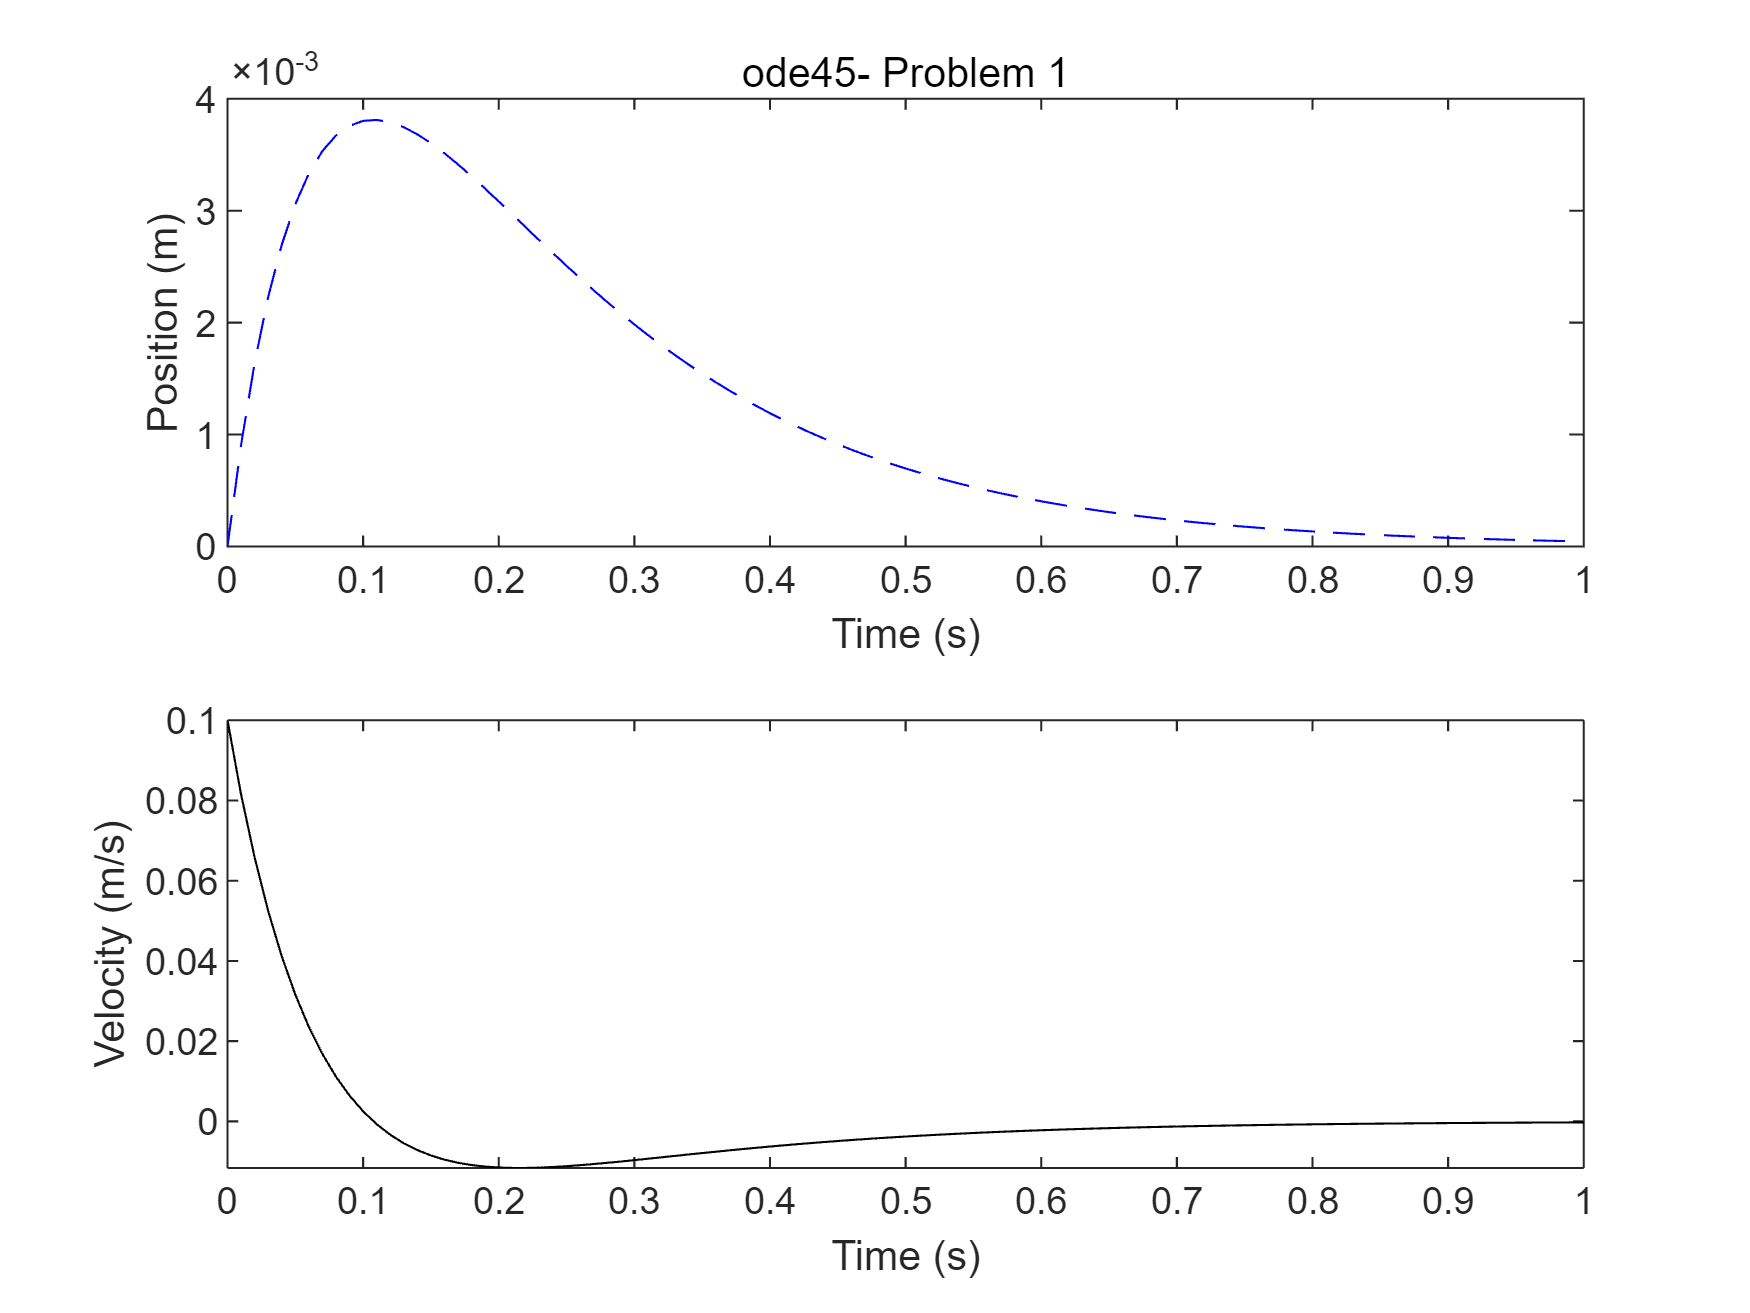

[Time, Y] = ode45(@mckFunc,tspan,Yini);

figure
subplot(2,1,1)
    plot(Time,Y(:,1),'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45- Problem 1')
subplot(2,1,2)
    plot(Time,Y(:,2),'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

## Problem 2

Find the displacement response y(t) and dydt(t) with  a sinusoidal input

Use  m=10kg ; k=800 N/m; c=200 N/(m/s), f=10Hz , h=0.01

F_dc=100*cos(2*pi*f*t);

### ode45()

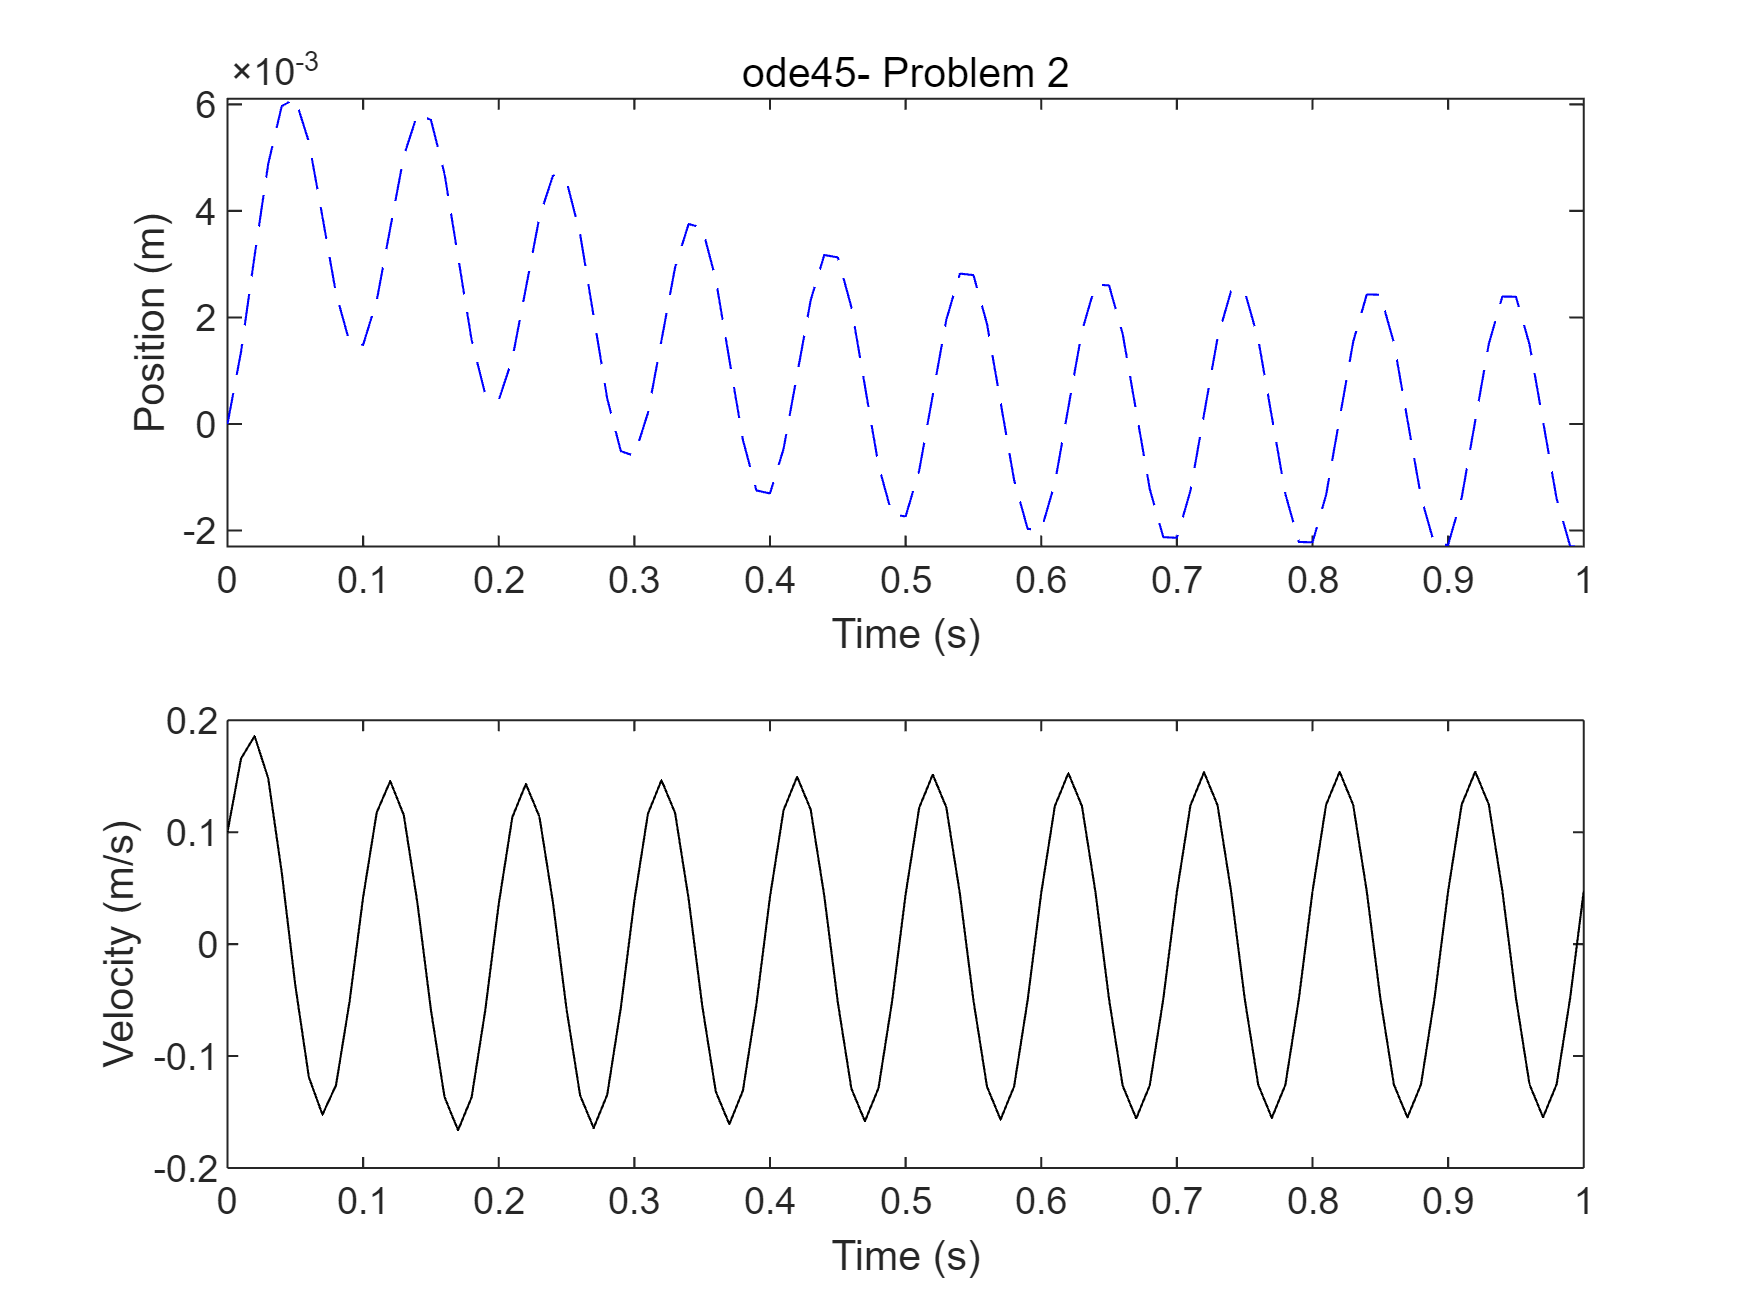

[Time, Y] = ode45(@mckFunc2,tspan,Yini);

figure
subplot(2,1,1)
    plot(Time,Y(:,1),'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45- Problem 2')
subplot(2,1,2)
    plot(Time,Y(:,2),'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

# **Linear Regression**

Find the best fit line for voltage-time measurement.

Measured at 1 second interval  (1~15sec)

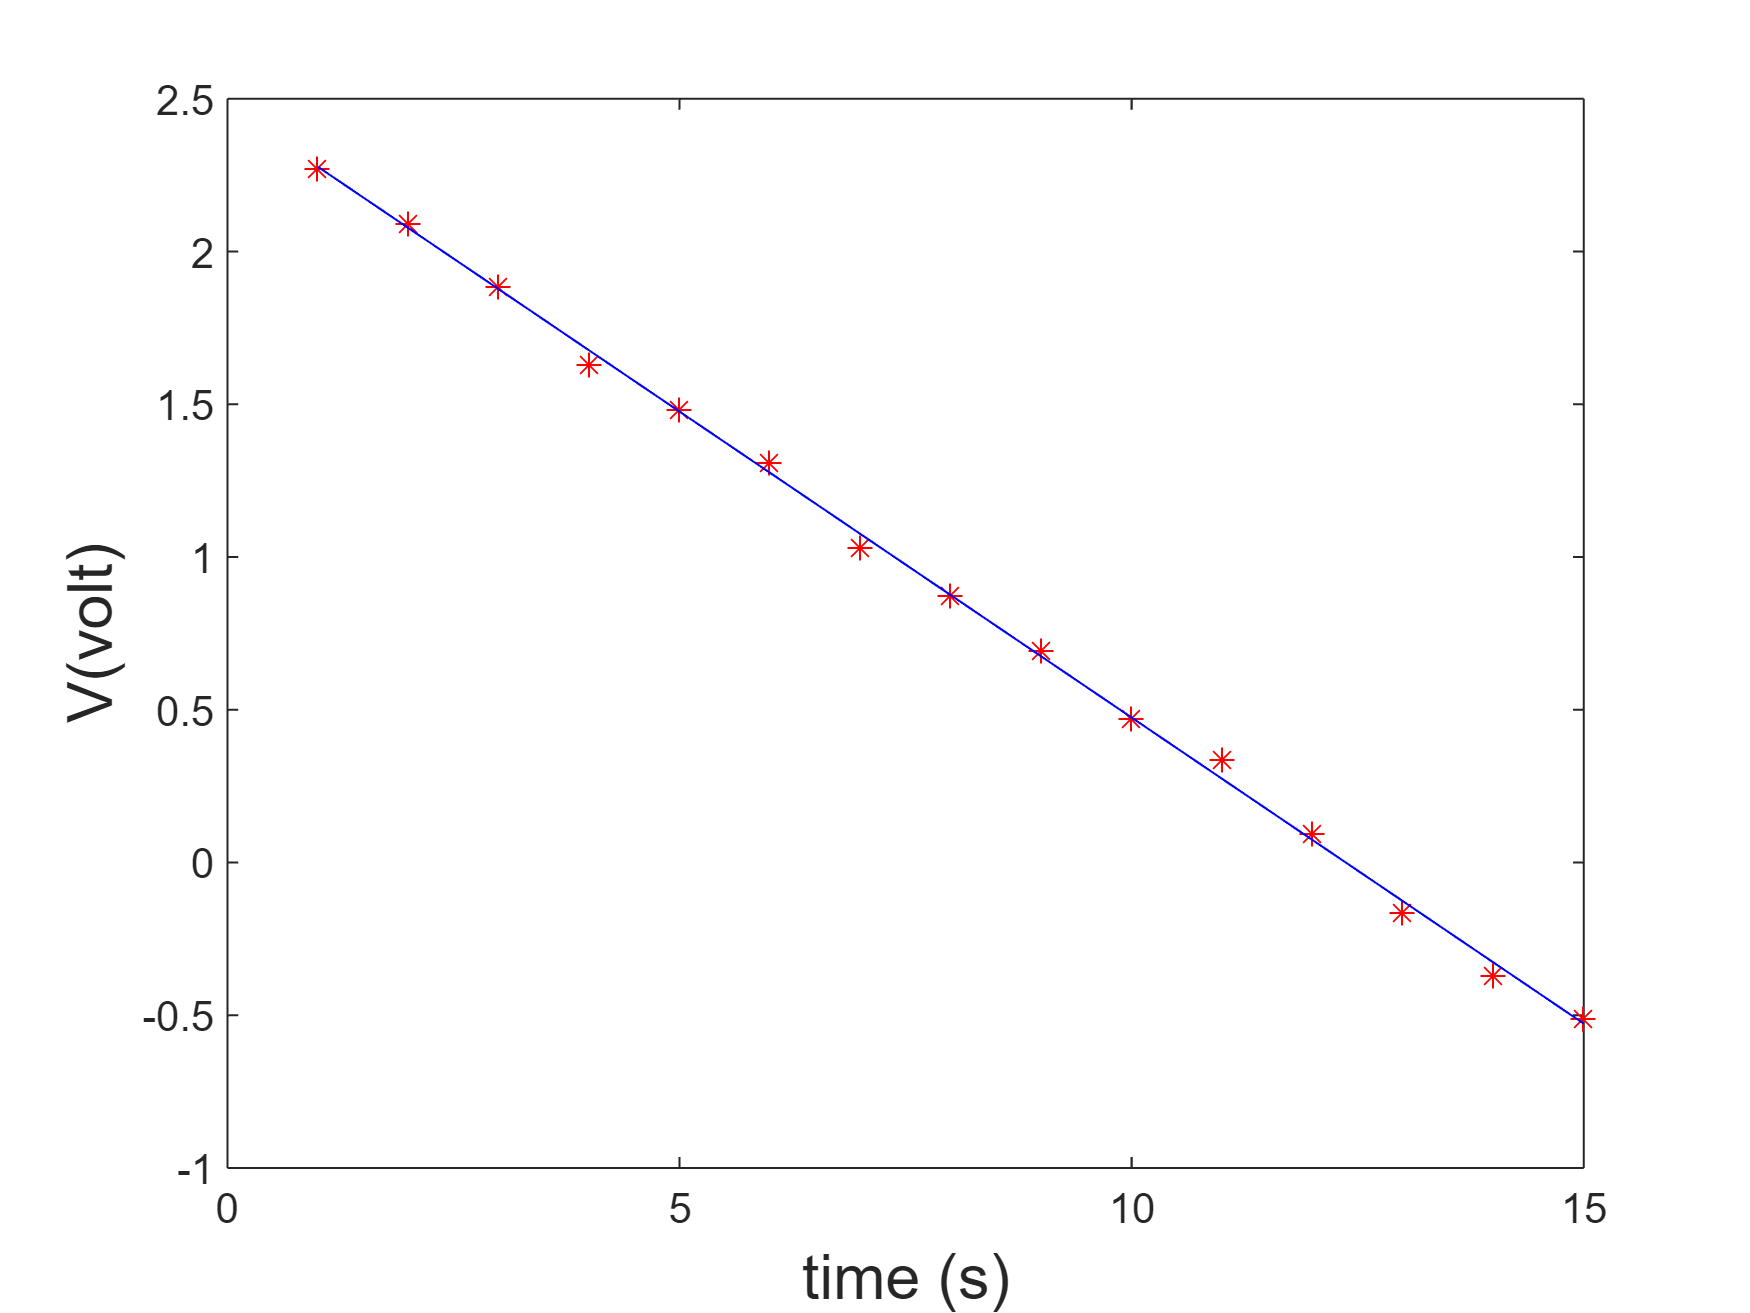

% Dataset
t = 1:1:15;
V=[2.272	2.092	1.887	1.629	1.482	1.308	1.030	0.875	0.693	0.470	0.336	0.095	-0.163	-0.371	-0.511];


% Least square regression
Zopt=polyfit(t,V,1);
Yopt=polyval(Zopt,t);  


figure
plot(t,V, '*r')
hold on
plot(t,Yopt, '-b')
xlabel('time (s)','fontsize',15)
ylabel('V(volt)','fontsize',15)

# **Exponential Fitting**

RC circuit with unknown capacitor C and resistor of 5M$\Omega$

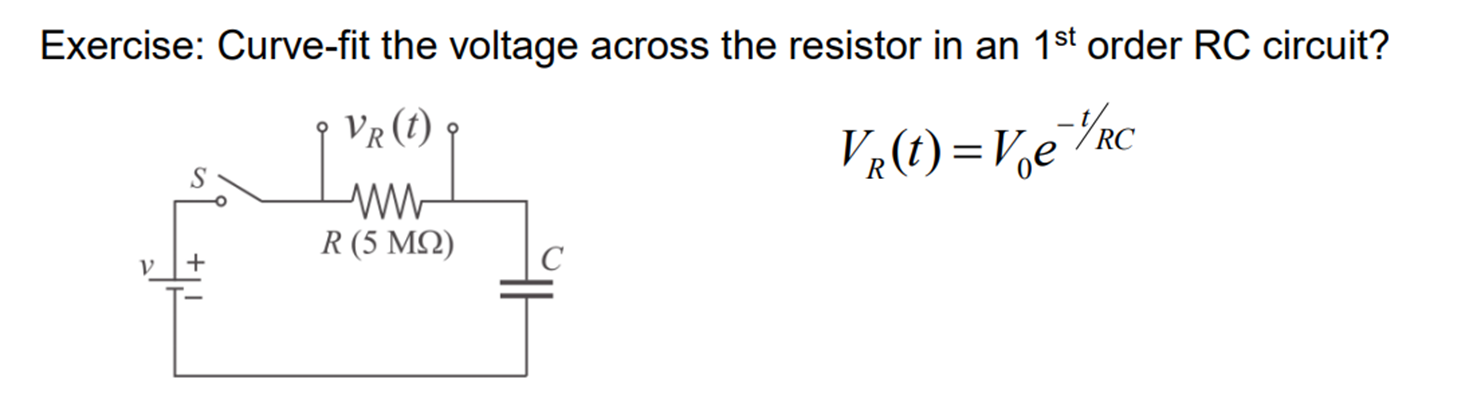

a) Find the capacitance  C from curve fitting

b) Esimate the voltage when time t=32sec

% Dataset
Xdata = 1:1:15;
Ydata = [9.7 8.1 6.6 5.1 4.4 3.7 2.8 2.4 2.0 1.6 1.4 1.1 0.85 0.69 0.6];
R=5e6;


% Exponential Fitting
Zopt=polyfit(Xdata,log(Ydata),1)

Zopt =    -0.2003    2.4776


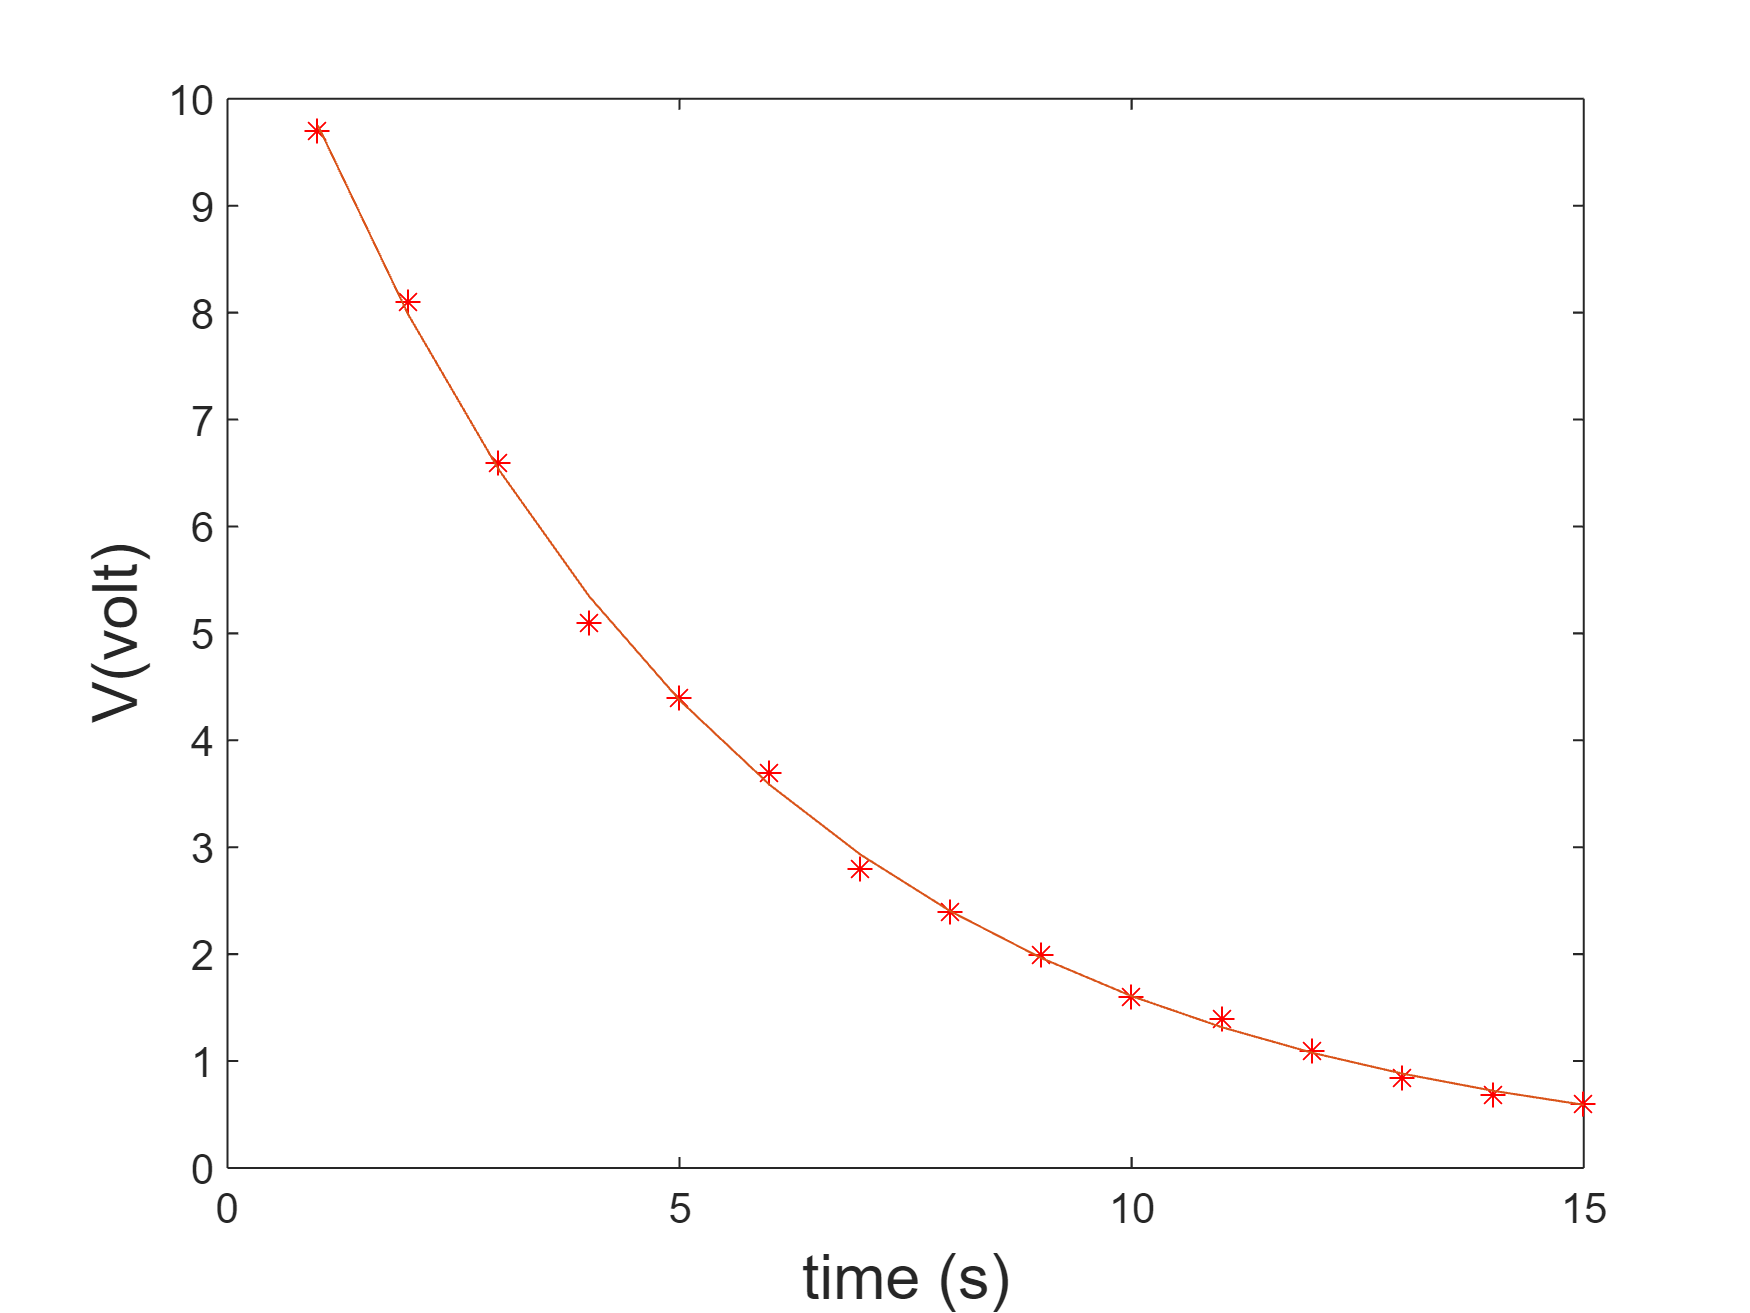

a0=Zopt(2);
a1=Zopt(1);
V0=exp(a0);
tau=-1/a1;
C=tau/R;
Yopt=V0*exp(-1/(R*C).*Xdata);

% Plot output
figure
plot(Xdata,Ydata, '*r')
hold on
plot(Xdata,Yopt)
hold on
xlabel('time (s)','fontsize',15)
ylabel('V(volt)','fontsize',15)

# **Function Definitions**

M-C-K without external force

function [dXdt] = mckFunc(t,x)
    dXdt=zeros(2,1); 
    m=10; k=800; c=200; f=10;
    FinDC=100;

    Fin=0*FinDC*cos(2*pi*f*t);
    dXdt(1)=x(2);
    dXdt(2)=1/m*(Fin-c*x(2)-k*x(1));
end

M-C-K with external force

function [dXdt] = mckFunc2(t,x)
    dXdt=zeros(2,1); 
    m=10; k=800; c=200; f=10;
    FinDC=100;

    Fin=FinDC*cos(2*pi*f*t);
    dXdt(1)=x(2);
    dXdt(2)=1/m*(Fin-c*x(2)-k*x(1));
end


The RC function is defined in @myRC(t,v)

function dvdx = myRC(t,v)
   tau=4.9919; T=1/tau;  Vm=0;
   dvdx =-T*v + 1*T*Vm;
end

